clear;close all;clc

syms t tau s t_p sigma

Delay Filter

f(t) = (1/tau)*exp(-t/tau)

$$f(t) = \frac{{\mathrm{e}}^{-\frac{t}{\tau }}}{\tau }$$

f(s) = laplace(f,t,s)

$$f(s) = \frac{1}{\tau \,\left(s+\frac{1}{\tau }\right)}$$

Photoreceptor Impulse Response

t_p = 20e-3;
sigma = 0.355;

v(t) = exp(-log10(t/t_p)^(2)/(2*sigma^(2)))

$$v(t) = {\mathrm{e}}^{-\frac{20000\,{\log\left(50\,t\right)}^{2}}{5041\,{\log\left(10\right)}^{2}}}$$

Numeric  Response

t_num = linspace(0,0.3,10000)';
Fs = 1/mean(diff(t_num));
v_num = double(subs(v,t,t_num));
u_num = zeros(length(t_num),1);
u_num(1) = 1;
v_num(1) = 0;
nx = 100;
y = [zeros(nx,1) ; v_num];
u = [zeros(nx,1) ; u_num];
FIG = figure (1) ; clf ; hold on
FIG.Units = 'inches';
FIG.Position = [2 2 4 4];
plot(t_num,v_num,'-k','LineWidth',1.5)
plot(t_num,u_num,'-r','LineWidth',1.5)
xlabel('Time (s)')
ylabel('V(t)')
title('Photoreceptor Impulse Response')
hold off

Transfer function estimation

photo = iddata(y,u,1/Fs);
Options = tfestOptions;
Options.Display = 'on';
Options.WeightingFilter = [];
tf1 = tfest(photo, 3, 0, Options)


tf1 =
 
  From input "u1" to output "y1":
                 1.205e09
  --------------------------------------
  s^3 + 280.7 s^2 + 3.207e04 s + 6.42e05
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 0
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "photo".
Fit to estimation data: 97.2%                     
FPE: 6.105e-05, MSE: 6.097e-05                    


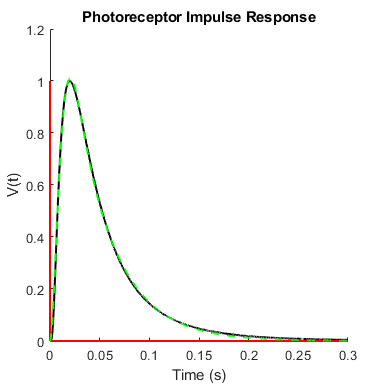

V = tf(tf1);

hold on
[y,t,x] = lsim(V,u_num,t_num);
plot(t,y,'--g','LineWidth',1.5)
hold off

1st Order Filter

test = tf(1,[20e-3 1]);
mag1 = bode(V);
mag2 = bode(test);
scl = max(mag1)/max(mag2);
sys = tf(scl,[20e-3 1]);

BODE Comparison

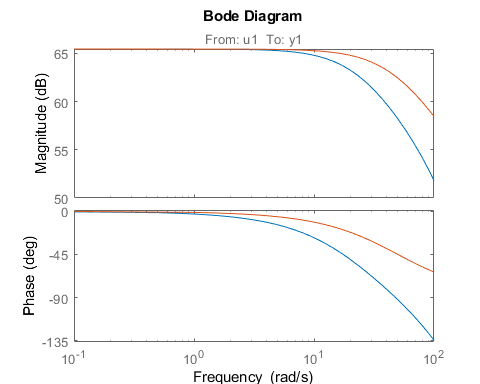

FIG = figure (2) ; clf ; hold on
FIG.Units = 'inches';
FIG.Position = [2 2 5 4];
bode(V) ; hold on
bode(sys)
xlim([10^(-1) 10^(2)])

Low-Pass FIlter Coefficents for Simulink EMD Model

lp_a = V.Numerator{1,1};
lp_b = V.Denominator{1,1};